# Criptografía visual

Cargo la imágen y transformo la imágen a binario para poder evaluar entre dos posibilidades y eliminar las escalas de grises

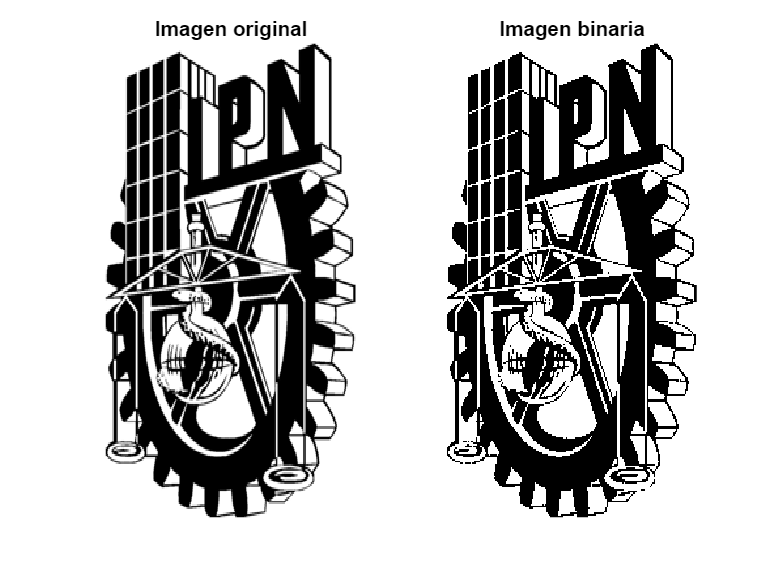

imbin = imbinarize(K);
figure(2);
subplot(1,2,1);
imshow(K);
title('Imagen original')
subplot(1,2,2);
imshow(imbin)
title('Imagen binaria')

Genero los bloques de datos para añadirlos posteriormente

A1 = [0,0;1,1];
A2 = [1,1;0,0];
B1 = [0,1;0,1];
B2 = [1,0;1,0];
C1 = [0,1;1,0];
C2 = [1,0;0,1];
CompA = [A1,A2];
CompB = [B1,B2];
CompC = [C1,C2];

Recorro toda la imágen para determinar cuando es un pixel blanco (1) y cuando es un pixel negro (0)

dimension = size(imbin);
vector_imbin = reshape(imbin, 1, []);
dim_vect_imbin = size(vector_imbin);

img1 = [];
img2 = [];

%imbin(2,1000)


Recorremos la imagen, por cada renglón reiniciamos una variable auxiliar que va a ser igual al renglón que equivale la representación de esos pixeles después de la asignación para cada  

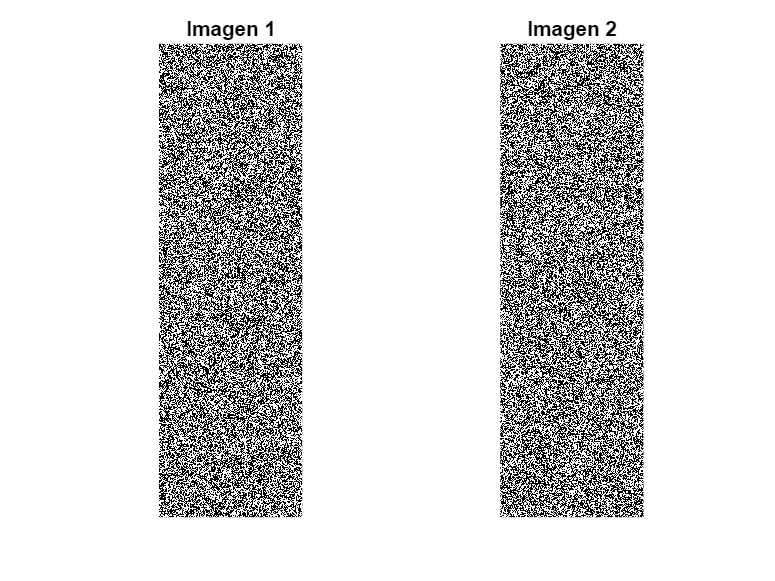

aux1 = [];
aux2 = [];

for i = 1 : dimension(1)
    aux1 = [];
    aux2 = [];
    for j = 1 : dimension(2)
        decision = randi(6);
        eval = imbin(i,j);
        if eval == 0
            switch decision
                case 1
                    aux1 = horzcat(aux1, A1);
                    aux2 = horzcat(aux2, A1);
                case 2
                    aux1 = horzcat(aux1, A2);
                    aux2 = horzcat(aux2, A2);
                case 3
                    aux1 = horzcat(aux1, B1);
                    aux2 = horzcat(aux2, B1);
                case 4
                    aux1 = horzcat(aux1, B2);
                    aux2 = horzcat(aux2, B2);
                case 5
                    aux1 = horzcat(aux1, C1);
                    aux2 = horzcat(aux2, C1);
                case 6
                    aux1 = horzcat(aux1, C2);
                    aux2 = horzcat(aux2, C2);
            end
        else
            switch decision
                case 1
                    aux1 = horzcat(aux1, A1);
                    aux2 = horzcat(aux2, A2);
                case 2
                    aux1 = horzcat(aux1, A2);
                    aux2 = horzcat(aux2, A1);
                case 3
                    aux1 = horzcat(aux1, B1);
                    aux2 = horzcat(aux2, B2);
                case 4
                    aux1 = horzcat(aux1, B2);
                    aux2 = horzcat(aux2, B1);
                case 5
                    aux1 = horzcat(aux1, C1);
                    aux2 = horzcat(aux2, C2);
                case 6
                    aux1 = horzcat(aux1, C2);
                    aux2 = horzcat(aux2, C1);
            end
        end
    end
    img1 = vertcat(img1, aux1);
    img2 = vertcat(img2, aux2);
end

figure(3)
subplot(1,2,1);
imshow(img1);
title('Imagen 1')
subplot(1,2,2);
imshow(img2)
title('Imagen 2')

Ahora hago la operación and con las dos imágenes binarias para poder decodificar el mensaje y ver la imagen original

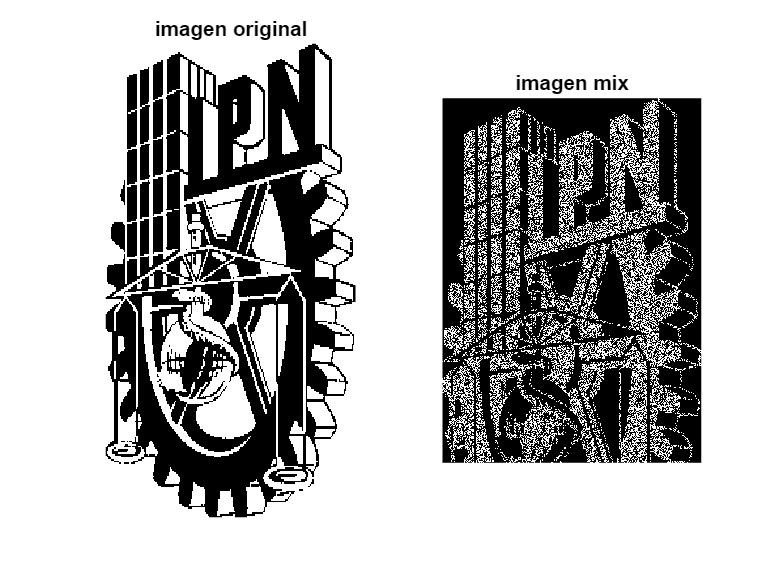

dimension_code = size(img1);
img_decode = zeros(dimension_code);
for i = 1 : dimension_code(1)
    for j = 1 : dimension_code(2)
        if (img1(i,j) && img2(i,j))
            img_decode(i,j) = 1;
        else
            img_decode(i,j) = img_decode(i,j);
        end
         %~(img1(i,j) & img2(i,j));
    end
end

figure(3)
subplot(1,2,1);
imshow(imbin);
title('imagen original');
subplot(1,2,2);
imshow(img_decode);
title('imagen mix');